# Dipole trap/Light sheet

Dipole trap beam parameters

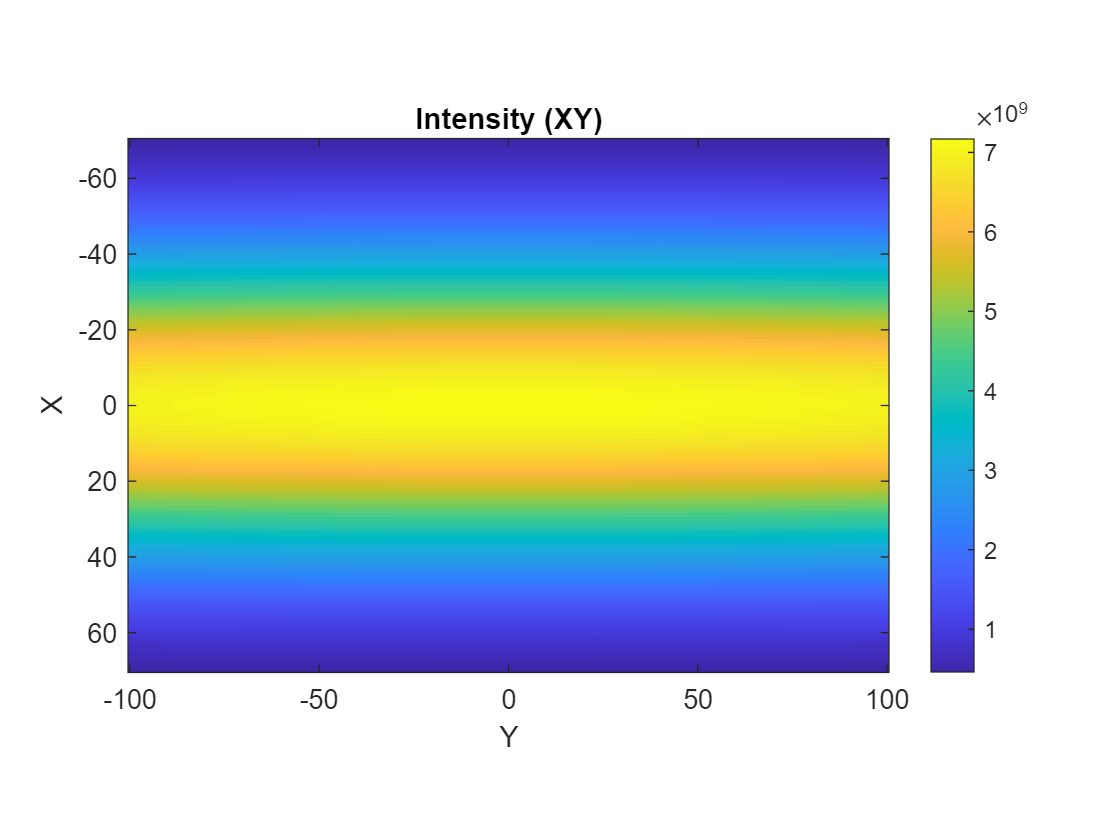

clear
clc

DipBeam.Power = 2500;
DipBeam.Pol = [45,90];
DipBeam.Wave = 1.064;
DipBeam.Ang = [90,90];
DipBeam.Waist = [3.7,60];
DipBeam.Phase = 0;

XRange = -70:70;
YRange = -100:100;
ZRange = -20:0.1:20;

XSize = length(XRange);
YSize = length(YRange);
ZSize = length(ZRange);

[Y,X,Z] = meshgrid(YRange,XRange,0);
[IXY,~,Pol] = gaussianFull(DipBeam,[X(:),Y(:),Z(:)]);
imagesc(YRange,XRange,reshape(IXY,XSize,YSize))
colorbar
daspect([1 1 1])
xlabel('Y')
ylabel('X')
title('Intensity (XY)')

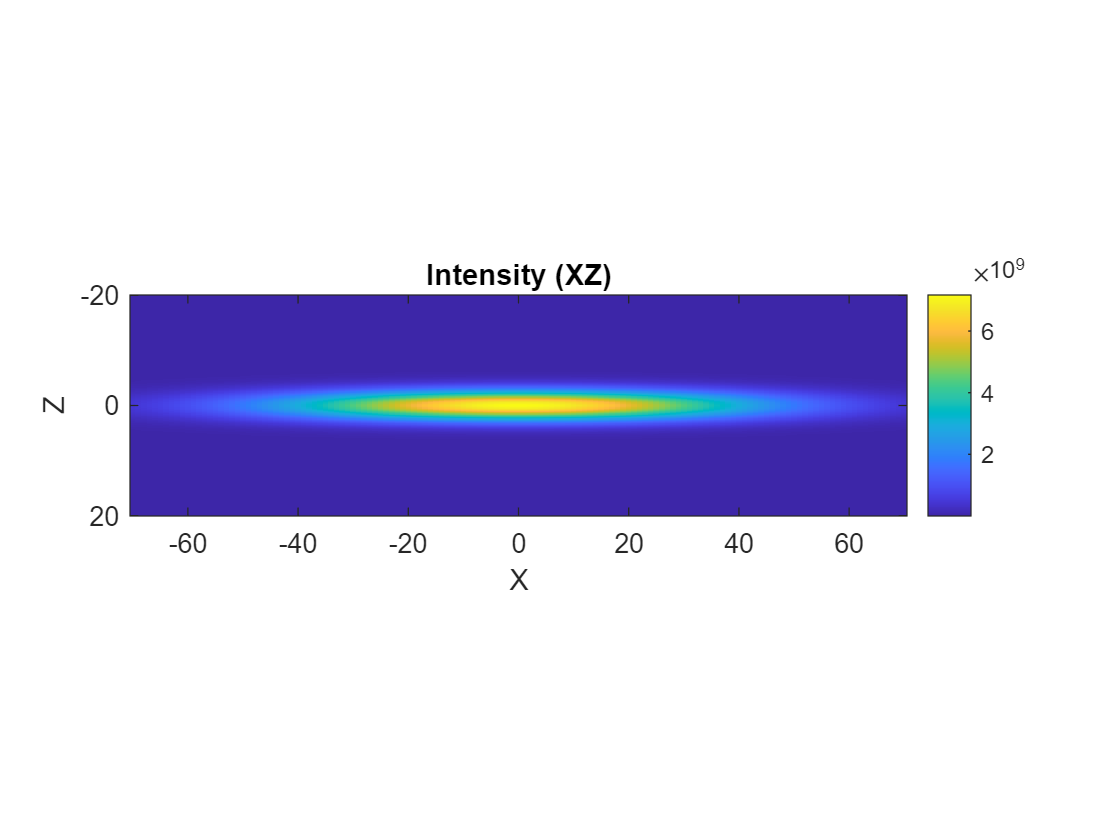

[Y,X,Z] = meshgrid(0,XRange,ZRange);
[IXZ,~,~] = gaussianFull(DipBeam,[X(:),Y(:),Z(:)]);
imagesc(XRange,ZRange,reshape(IXZ,XSize,ZSize)')
colorbar
daspect([1 1 1])
xlabel('X')
ylabel('Z')
title('Intensity (XZ)')

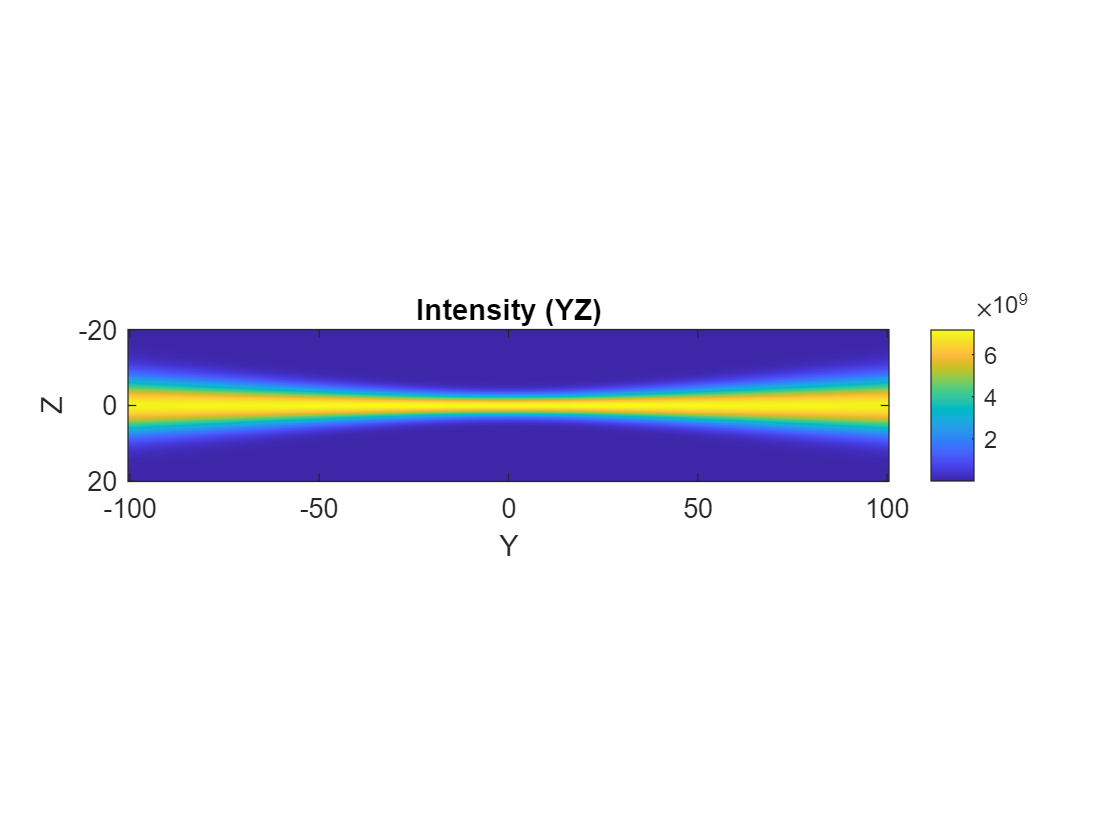

[Y,X,Z] = meshgrid(YRange,0,ZRange);
[IYZ,~,~] = gaussianFull(DipBeam,[X(:),Y(:),Z(:)]);
imagesc(YRange,ZRange,reshape(IYZ,YSize,ZSize)')
colorbar
daspect([1 1 1])
xlabel('Y')
ylabel('Z')
title('Intensity (YZ)')

#### Static light shift

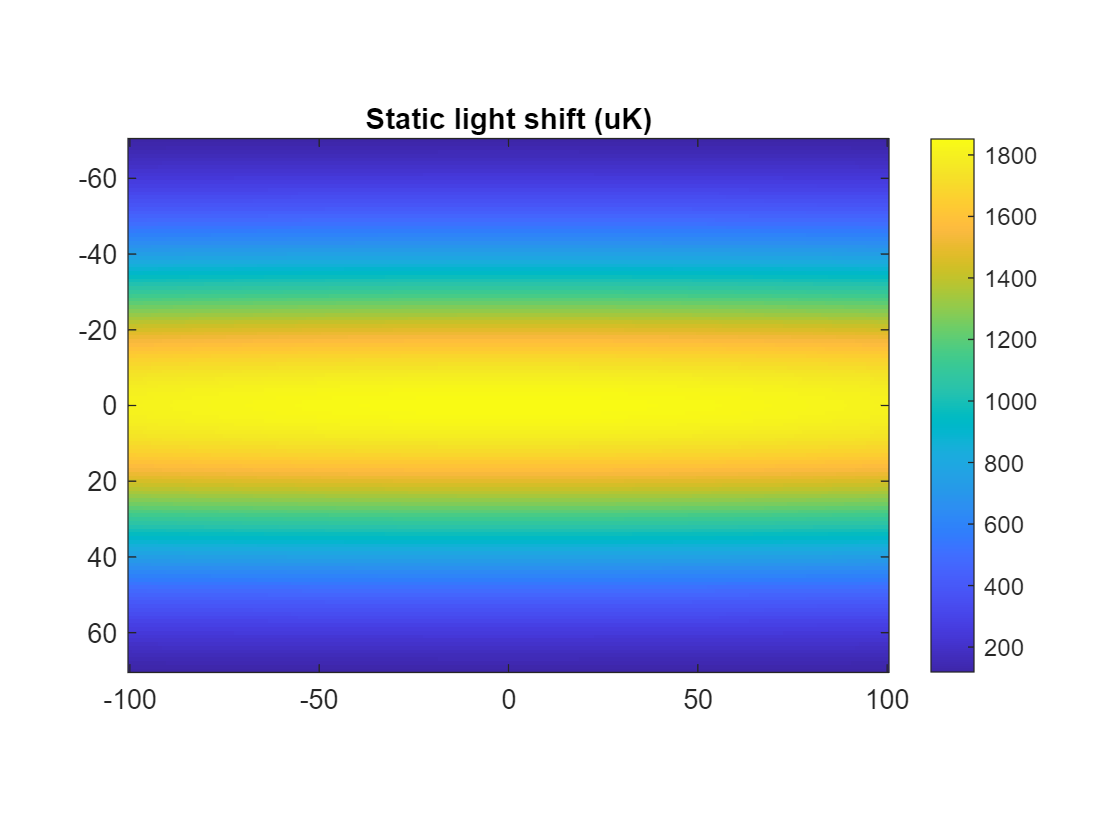

PotentialStatic = aNLJ('s',6,0,1/2,DipBeam.Wave,'ExpuK')*reshape(IXY,XSize,YSize);
imagesc(YRange,XRange,PotentialStatic)
colorbar
daspect([1 1 1])
title('Static light shift (uK)')

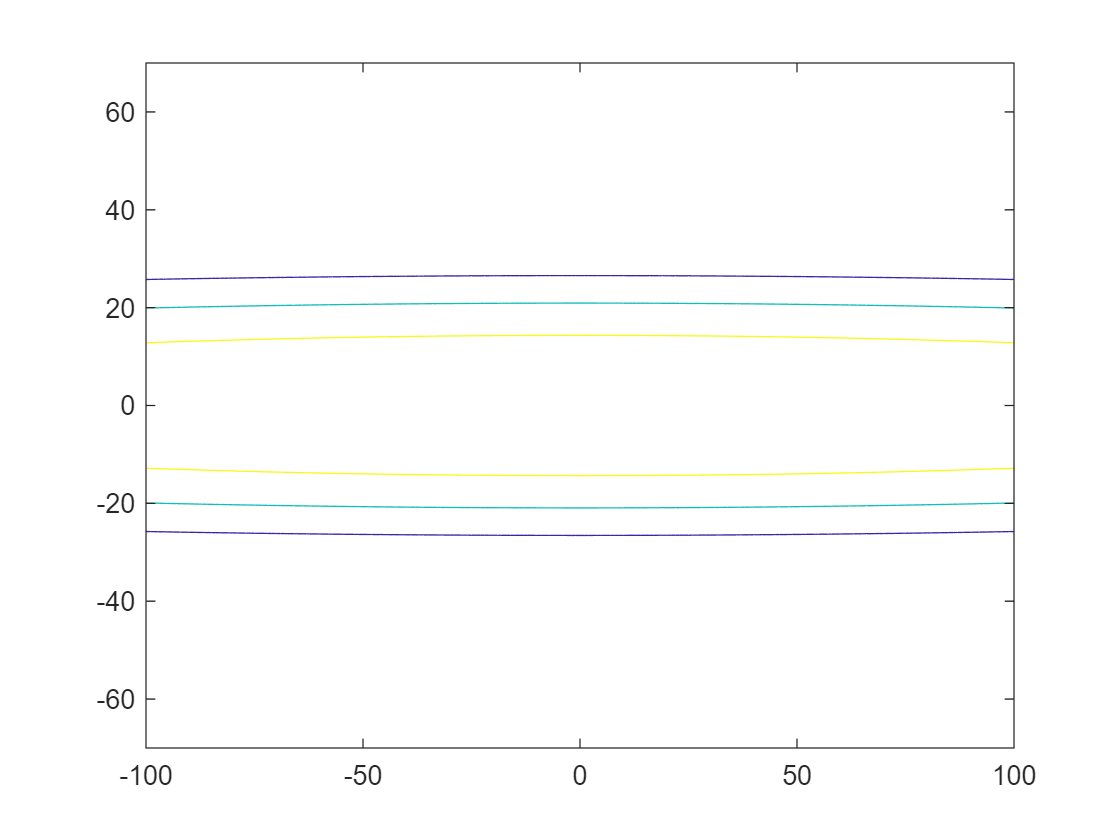

contour(YRange,XRange,PotentialStatic,max(PotentialStatic(:))+[-200,-400,-600])

#### Transition frequency shift

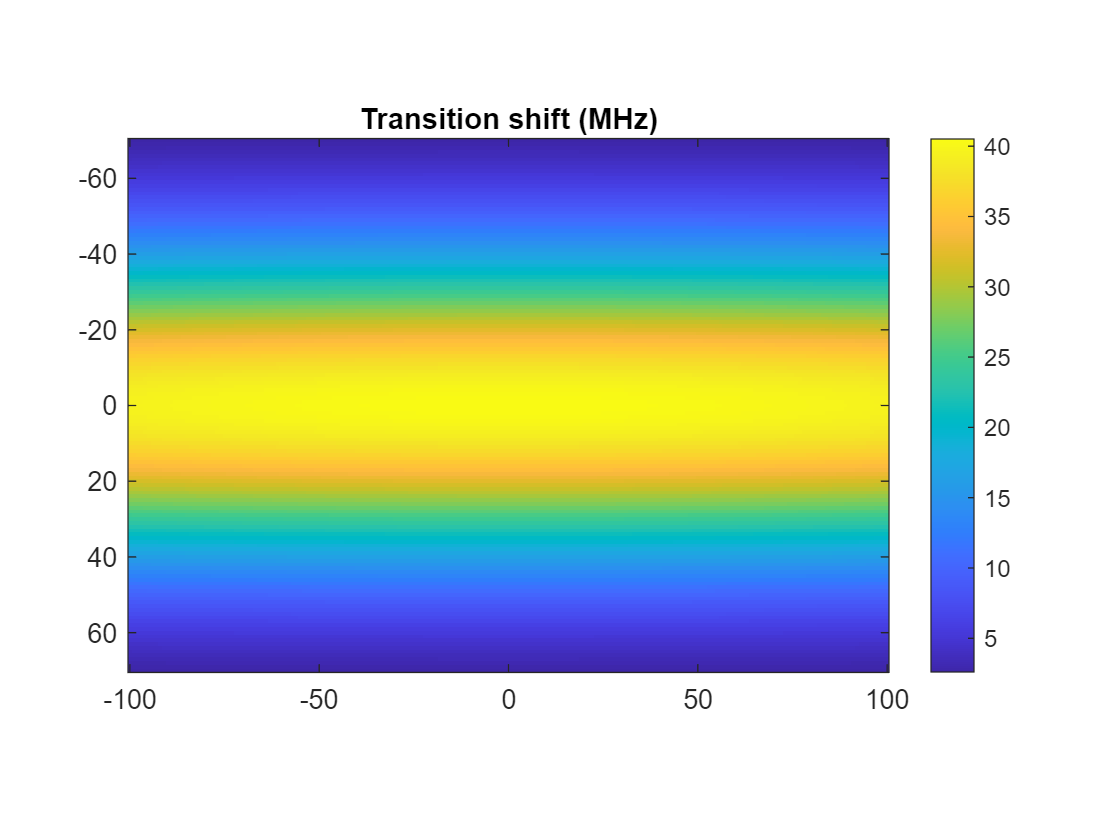

DiffPolarizability = aNLJ('s',6,0,1/2,DipBeam.Wave,'ExpHz')-aNLJ('s',6,1,3/2,DipBeam.Wave,'ExpHz');
TransitionShift = DiffPolarizability*reshape(IXY,XSize,YSize)*1e-6;
imagesc(YRange,XRange,TransitionShift)
colorbar
daspect([1 1 1])
title('Transition shift (MHz)')

#### Effective magnetic field

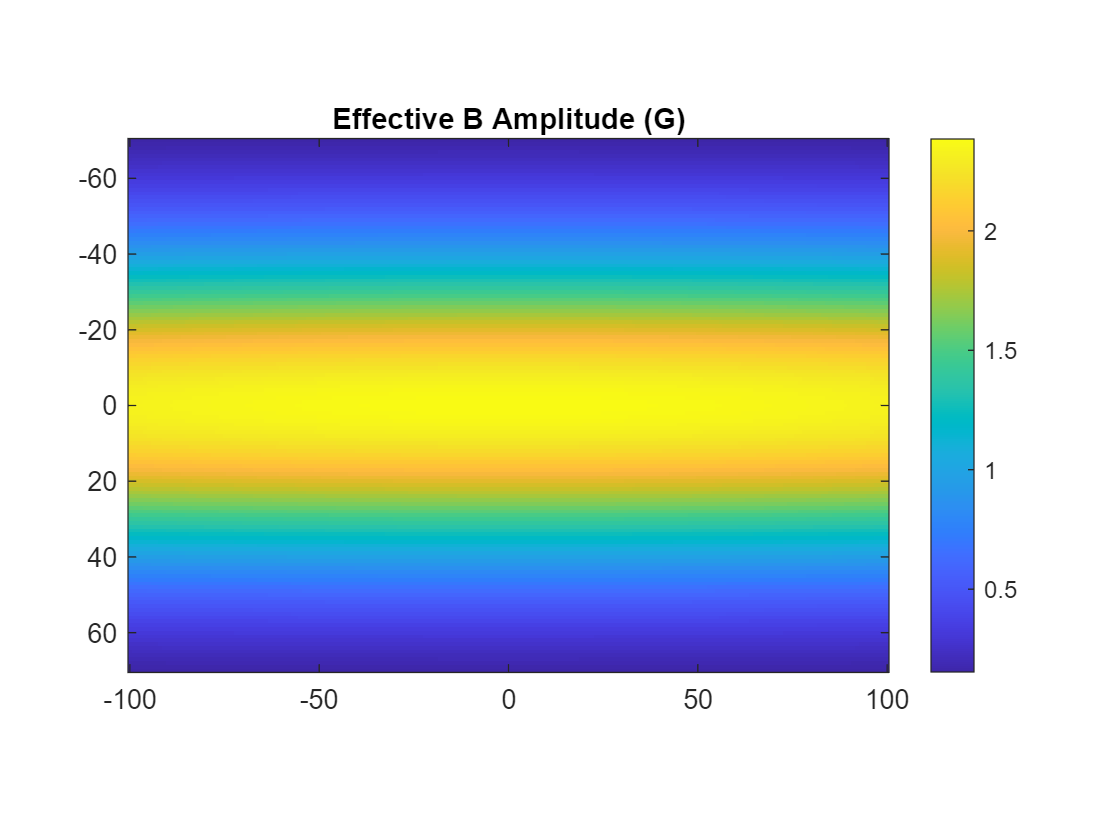

EffB = aNLJ('v',6,0,1/2,DipBeam.Wave,'ExpBFict')*1i*cross(conj(Pol),Pol,2).*IXY;
EffBAmp = reshape(vecnorm(EffB,2,2),XSize,YSize);

imagesc(YRange,XRange,EffBAmp)
colorbar
daspect([1 1 1])
title('Effective B Amplitude (G)')

#### Trap frequency

[Freq,Vec] = fitTrapFreq([0 0 0], ...
    @(x) aNLJ('s',6,0,1/2,DipBeam.Wave,'Exp')*gaussianFull(DipBeam,x))

Freq = 1.0e+04 *

    0.0115
    0.1806
    2.9278


Vec =     0.0000   -1.0000   -0.0000
    1.0000    0.0000   -0.0000
    0.0000   -0.0000    1.0000
